# Introduction to Neural Networks (Lecture Edition)

## 1. Modeling image and text data 

### Challenging unsolved biomedical problems 

#### A. Anomaly detection

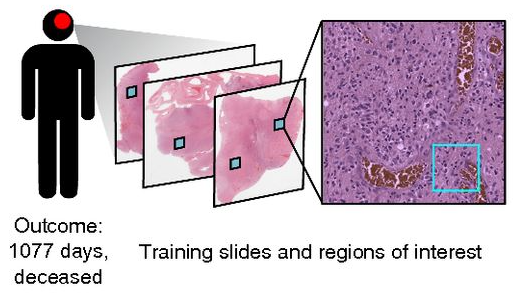

Image taken from Mobadersany et al., (2018). Predicting cancer outcomes from histology and genomics using convolutional networks. *Proceedings of the National Academy of Sciences*, *115*(13), E2970-E2979.

#### B.  Modeling EHR data for prognosis prediction

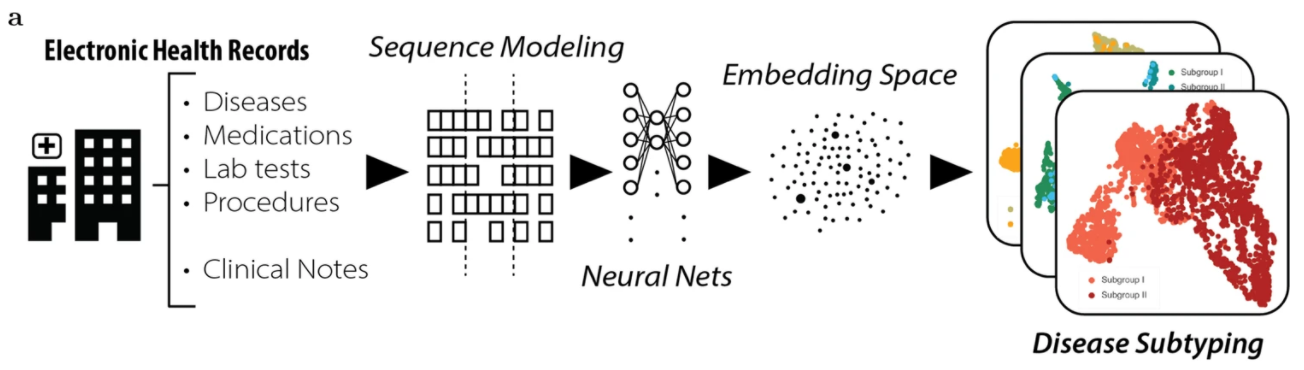

Image taken from Landi et al., (2020). Deep representation learning of electronic health records to unlock patient stratification at scale. *NPJ digital medicine*, *3*(1), 1-11.

### Why traditional machine learning algorithms don't work with complex biomedical data

- Several (non-realistic) model assumptions.

- The need for feature engineering.

- Specific use-cases

### Why neural networks?

- No underlying model assumptions.

- Less of a need for human intervention.

- Generalizable: modular, transferrable, and customizable.

### Why not neural networks?

- High data requirements.

- Lack of model interpretibility.

- Training time.

## 2. Neural network primer

We'll briefly cover essential theoreticals to get started trarining neural nets, including:

- Components

- Model training

- Model optimization

### The anatomy of a neural network

###  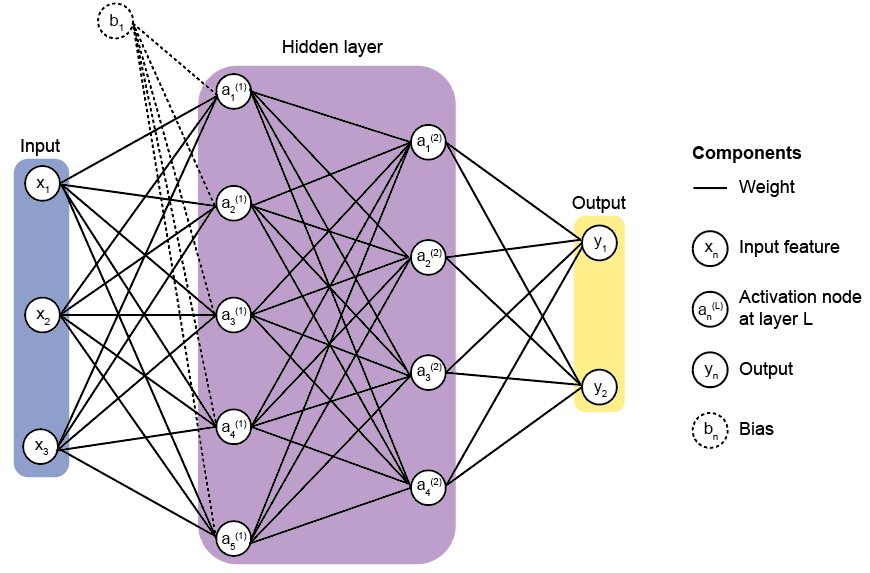

**Take-home message:** a neural network feeds data (**input layer**) into the **hidden layer** - a modular stack of equations that combines the data in a very non-linear way. The numbers returned in the **output layer** correspond to floating values (regression) or a probability of a given class (classification). 

### Model training

Training a neural network requires us to iterate 3 distinct phases for n times (**epochs**) until we reach a stable objective value (e.g., minimize cost). 

**The three phases are:**

- Forward propagation

- Solve the objective function

- Backward propagation and weight update

#### A. Forward propagation

**What is forward propagation?**

**Forward propagation** is the process of fitting a model with weights (analagous to regression coefficients) and transforming the data to be very non-linear. 

When starting from the very beginning, we initialize the weights with small random numbers.

**Introducing non-linearity with activation functions**

*Sigmoid function (logistic regression)*

One way to transform the data is to use the **sigmoid activation function. **This scales the data to assume a range of [0, 1], and is equivalent to performing **logistic regression**. 

The form of a normal sigmoid distribution is shown below.

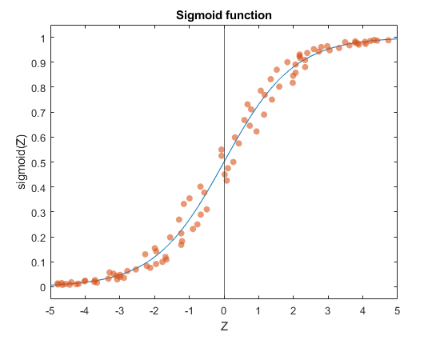

**Take-home: **This function is particularly useful to get probabilities for a **binary classification problem**.

**How is this different from traditional ML?**

Fitting data to a linear equation (linear regression) or taking the sigmoid of the linear equation (logistic regression) are algorithms by their own right. However, **neural networks are modular**: we can stack these equations together into segments called layers.

**{INSERT IMAGE}**

The computations performed in the hidden layer give rise to very complex combinations of data. This allows us to model non-linear data very easily, while throwing out typical model assumptions, like normality.

#### B. Solve the objective function

Next, we need to see how right or wrong our model is by computing the objective value. In most cases, we're interested in computing the cost value. For regression, we typically use the **mean-squared error**. For binary classifiication, we use** cross-entropy**. 

**Important note **

The loss function for a multi-class classification problem is called the **softmax** function, and this is a generalization of cross-entropy. This is the activation function we will use in the lab section of this lecture.  

#### C. Backward propagation and weight update with gradient descent

**What is backward propagation?**

**Motivation:** We just computed the global model error. However, to make our model learn better weights, we need to figure out how each weight contributed to this error. 

**Backward propagation** is the process of telling us where the errors occurred in forward propagation, starting from the cost value and working our way backwards. By computing the error contribution for each weight, we can use gradient descent to tweak individual weights to get a more accurate answer.

#### Summary

We just went through one epoch of model training. In practice, we would (and we will) iterate this process several more times to get our final model.

To summarize the process of training a neural network,** the three phases of training involve:**

- **Forward propagation:** fitting the data with model weights across several layers.

- **Solve the objective function**, such as the model cost.

- **Backward propagation and weight update** to get a more accurate model in the next epoch.

## 3. Lab 1. Training shallow feedforward neural networks

To practice training neural networks, we'll train a **shallow neural network**: a neural network with few layers. Information is only fed into the next adjacent layer (and not back into previous layers), making this a **feedforward neural network**. 

- This is in contrast to **recurrent neural networks**, where information can travel back to the previous layer. This is beyond the scope of this lecture, but you can find additional information in the **appendix**. 

**Our task:** We'll focus on a binary classification problem to predict whether or not a patient has metastatic breast cancer, given some imaging data that has been engineering into 7 features. 

### Description of the dataset

This built-in MATLAB dataset can be called using the `load cancer_dataset `command, and a comprehensive description of the dataset can be found by typing in `help cancer_dataset`. 

- The **input** is a matrix of 9 features from 699 biopsies. The **features** include attributes such as adhesion, cell size, and cell shape. These are stored in the `cancerInputs` variable. 

- The **output** `cancerTargets` variable is a 2 x 699 matrix, where the first row corresponds to benign, and the the second row corresponds to malignant. 

### A. Load the breast cancer image classification dataset

Let's load the breast cancer image classification dataset we've been using for the last two lectures. The MATLAB built-in functions process datasets where the features/target variables span the rows, while the observations span the columns.

clear all; 
load cancer_dataset.mat

X = cancerInputs;
Y = cancerTargets;

### B. Setting the shallow neural network architecture

Next, let's specify the neural network architecture using the patternnet function. We'll set 10 nodes in the hidden layer and train with gradient descent.

numOfActivationNodes = 10;        % 1 hidden layer with 10 nodes in the hidden layer
optimizationFnc      = 'traingd'; % Gradient descent optimization algorithm
net                  = patternnet(numOfActivationNodes, optimizationFnc)

### C. View the network structure with MATLAB's GUI

Let's view the network structure `net` using the `view` function, which utilizes MATLAB's GUI. 

view(net)

The popup screen should show you the following information:

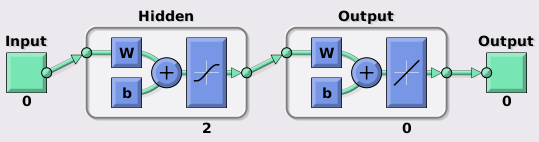

### D.Setting up the network hyperparameters

**Hyperparameters** are user-set parameters that will affect the model performance. Some examples we've seen so far are the number of nodes and number of layers in a network.

Most of the hyperparameters can be modified by setting the fields in the `net` structure. We won't go over each individual hyperparameter here (the documentation to modify some training parameters can be found in this [link](https://www.mathworks.com/help/deeplearning/ref/traingda.html)), but we'll discuss commonly adjusted hyperparameters.

#### Validation sets

To divide the data for training, validation, and testing, we can specifying some fields in the `net` structure we made from the `fitnet` function.

net.divideParam.trainRatio = 0.7; % Training set size
net.divideParam.testRatio  = 0.2; % Test set size during each cross validation fold
net.divideParam.valRatio   = 0.1; % The final validation set reported

During the training phase, if you input the entire dataset, it automatically splits the dataset into three groups: 60% training, 20% testing (holdout), and an additional 20% for cross validation accuracy determinination. 

#### Loss functions

By default, the loss function is specified as the mean squared error. We'll use the MATLAB default argument, but if we wanted to compute classification errors using the cross entropy loss function, we need to specify the `crossentropy` function using the following syntax:

#### Epochs

The number of epochs can be specified by setting the `net.trainParam.epochs` parameter. While MATLAB performs 1000 epochs by default, we'll set it to 10,000 epochs just to ensure we'll fully train the model. 

net.trainParam.epochs      = 5000;

MATLAB performs **early stopping - **it stops training the model when the model error increases during an epoch. This is a nice feature to implement that helps the model avoid overfitting. 

### F. Training the shallow neural network

Let's now train the shallow neural network using the `train` function. This will show a new window while the model is training to track the performance in real-time. An example of the window is shown below.

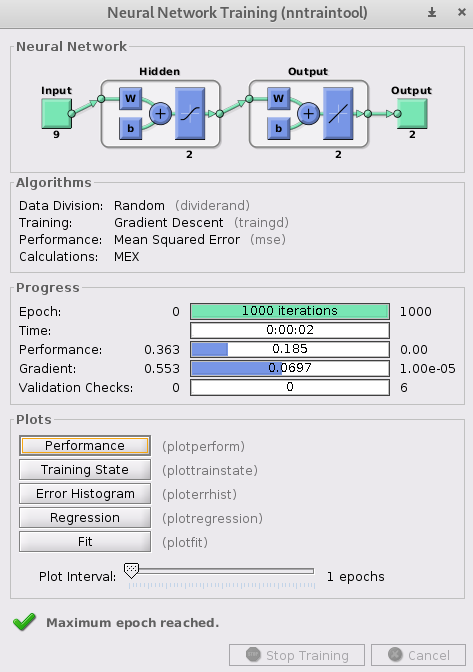

`train` takes in the structure we declared (`net)`, the input data (X), and the target labels (Y), and outputs the trained neural network (`trainedNet)`, as well as the computed metrics during training (`trainingRecord)`. 

net.trainParam.showWindow  = 1; 
[trainedNet, trainingRecord] = train(net, X, Y);

### G. Computing model predictions and evaluating model performance

First, we'll compute our predictions using the test dataset. The trained neural network `trainedNet` also acts as function to compute predictions. We can use the following syntax to compute the predicted Y values from the test set.

ypred = trainedNet(X)

From here we can use the methods we described previously to evaluate the model. To evaluate the model's performance, we can use the built-in `perform` function, which has the following syntax:

error = perform(trainedNet, Y, ypred)

### H. Plotting model metrics 

#### Cost Curves

We can plot the cost curves we've generated previously using the `plotperf` function. Note that the error is in log-scale, unlike the plots we have computed previously. Additionally, it plots the training error, test error, and validation error as separate cost curves.

figure;
plotperf(trainingRecord)

#### Confusion matrix

To evaluate the average and individual class accuracies, we can use a confusion matrix.

figure;
plotconfusion(ypred, Y);
title("Shallow neural network results");
xlabel("True"); ylabel("Prediction");
xticklabels(["Benign", "Malignant"]);
yticklabels(["Benign", "Malignant"]);

## 4. Lab 2. Training deep feedforward neural networks

We'll train a **deep neural network**: a neural network with many layers. 

A general trend with deep neural networks is that the more nodes and more layers you add, the more accurate the model becomes. However, tradeoff is that this increases the computation time and the risk of overfitting.

### A. Load and preprocess the breast cancer image classification dataset

MATLAB has made it easy to construct deep neural networks by simply using the `trainNetwork` function. It takes in the datasets $X_{\textrm{train}}$ and $Y_{\textrm{train}}$, the network architecture as the third argument, and the hyperparameter specifications in the 4th argument. We'll use the breast cancer imaging dataset to train and test this deep neural network.

clear all; rng(2);
load cancer_dataset.mat

X = cancerInputs;
Y = cancerTargets;

% Initialize params for trainTestSplit
trainingSize = 0.8; randomstate = 2;

% Split the dataset into training and test sets.
[Xtrain, Ytrain, Xval, Yval] = ...
    trainTestSplit(X', Y', ...
    trainingSize, randomstate);

% Re-format so the DLT can use the data
Xtrain = Xtrain';              Xval = Xval';
Ytrain = categorical(Ytrain'); Yval = categorical(Yval');

### **B. Declare the model architecture**

**There are 4 components we need to specify in the **`layer`** array:**

- **Input data layer**: the specific function differs on the data type inputed. For numerical data, the `sequenceInputLayer` is the appropriate function, which needs the number of features as the parameter.

- **Hidden layer architecture**: the specific architecture needed to design a feedforward neural network is the `fullyConnectedLayer`, which needs the number of activation nodes as the first parameter. The `WeightsInitializer` and `BiasInitializer` parameters tell the function how to initialize the parameters, using small random numbers from a normal distribution.

- **Activation function**: Between each `fullyConnectedLayer` is the activation function. The `softmaxLayer` is the activation function we will use.

- **Classification layer** (optional): The `classificationLayer` transforms the values to their predicted labels.

% Specify neural network architecture
layers = [...
    
    sequenceInputLayer(size(X, 1)), ...            % Input data layer

    fullyConnectedLayer(10, ...                         % Hidden layer 1 with 10 nodes
    'WeightsInitializer', 'narrow-normal', ...
    'BiasInitializer', 'narrow-normal'), ...
    
    softmaxLayer, ...                                   % Activation function 1
    
    fullyConnectedLayer(5, ...                         % Hidden layer 2 with 5 nodes
    'WeightsInitializer', 'narrow-normal', ...
    'BiasInitializer', 'narrow-normal'), ...
    
    softmaxLayer, ...                                   % Activation function 2
    
    fullyConnectedLayer(3, ...                         % Hidden layer 3 with 3 nodes
    'WeightsInitializer', 'narrow-normal', ...
    'BiasInitializer', 'narrow-normal'), ...
    
    softmaxLayer, ...                                   % Activation function 3
    
    fullyConnectedLayer(2, ...                          % Output layer with 2 nodes
    'WeightsInitializer', 'narrow-normal', ...
    'BiasInitializer', 'narrow-normal'), ...
    
    softmaxLayer, ...                                   % Transform to probabilities
    
    classificationLayer ...                             % Label encode
]
analyzeNetwork(layers)

Next, we have to specify the model hyperparameters. The `trainingOptions` function creates a model object that lets you feed in the hyperparameters into the neural network function. The specific arguments we will use are shown below.

% Spcify hyperparameters for neural network
options = trainingOptions(...
    'adam', ...                                   % Adam optimization
    'InitialLearnRate', 0.01, ...                 % Set the initial learning rate to 0.01 
    'MaxEpochs', 200, ...                        % Maximum number of epochs to train algorithm
    'ValidationData', {Xval, Yval(1, :)}, ...         % Dataset to use as the validation set
    'ValidationFrequency', 30, ...                % Frequency to validate the network at regular intervals
    'Verbose', true, ...                          % Outputs information about training 
    'Shuffle', 'every-epoch', ...                 % Data shuffling for every epoch
    'Plots', 'training-progress' ...              % Show plots for every epoch
);                

### B. Description of the model architecture

Now, we need to specify the neural network architecture. We will store the network as an array called `layers`. We'll be constructing a deep neural network that has the following structure:

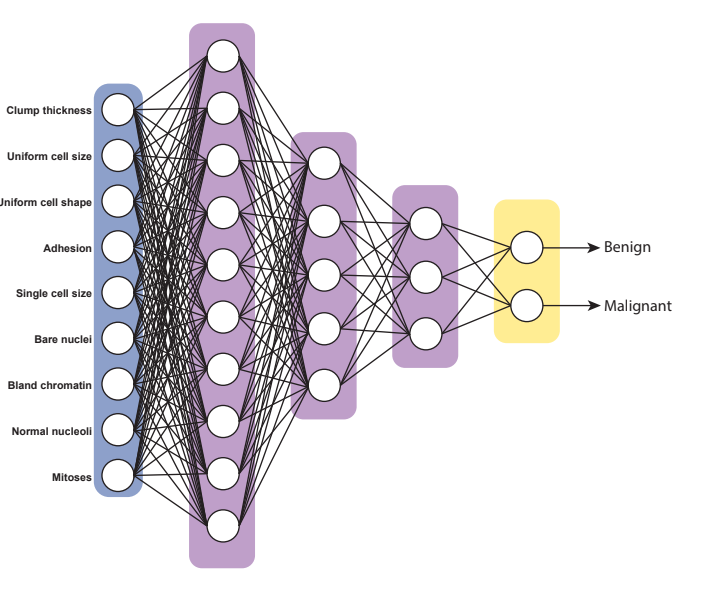

## 5. Lab 3. Model optimization

#### Data scaling

#### Regularization

#### Dropout

#### Early stopping

#### Hyperparameter tuning

#### Parallel computing

## 5. Convolutional neural networks

## 6. The object detection problem